x = 20;
disp(x);   % Display value of x

    20




x = 5.6789;

disp('Value of x:')

Value of x:


%used for quickly display the result and add newline automatically(no formatting)
disp(x)

    5.6789




fprintf('Value of x: %.2f\n', x)   %display formatted result

Value of x: 5.68


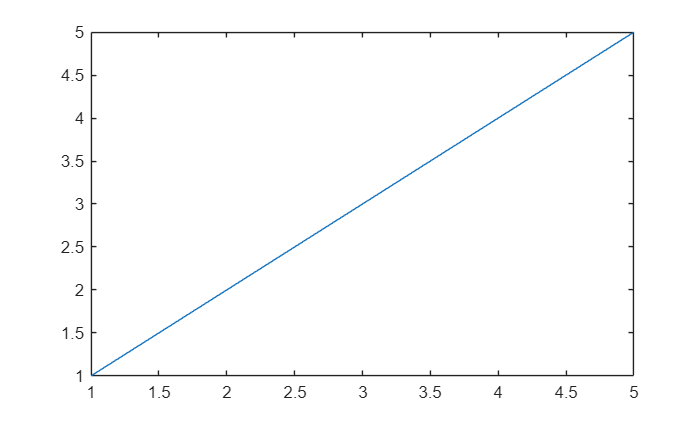


plot(1:5, 1:5)
%not for display/printing text
print('lineplot.png','-dpng')      % saves the current figure as an image

% ctrl+alt+enter (to break in such a way)
% ctrl+enter (to run the code)

% help will display what that function does and how it work
% doc on other hand redirect to matlab website and then show a proper work

%assgining the variable
a = 5;          % Scalar
b = [1 2 3];    % Row vector
c = [1; 2; 3];  % Column vector
c_size1=size(c,1)%size of c

c_size1 = 3

c_size2=length(c)

c_size2 = 3


d = [1 2; 3 4]; % Matrix

%basic math
a = 5;
b = 3;

sum = a + b;
diff = a - b;
prod = a * b;
div = a / b;
pow = a ^ b;

% element wise operation
A = [1 2 3];
B = [4 5 6];
C = A .* B;   % Multiply element-by-element
D = A ./ B;   % Divide element-by-element
disp(C)

     4    10    18



disp(D)

    0.2500    0.4000    0.5000



%build in function
disp(sqrt(16))        % Square root

     4



disp(log(10))         % Natural log

    2.3026



disp(log10(1000))     % Log base 10

     3



disp(sin(pi/2))       % Sine function

     1



disp(mean([1 2 3]))   % Average

     2



disp(max([1 4 2]))    % Maximum

     4



%creating the array
x = 1:5;           % 1 2 3 4 5
y = 0:2:10;        % 0 2 4 6 8 10 (start:step:end)
z = linspace(0,1,6); % 0 0.2 0.4 0.6 0.8 1 (equally spaced)

disp(x)

     1     2     3     4     5



disp(y)

     0     2     4     6     8    10



disp(z)

         0    0.2000    0.4000    0.6000    0.8000    1.0000



% using the indexing
%indexing start with 1
A = [10 20 30 40];
A(2)       % Second element → 20

ans = 20

A([1 3])   % First and third elements → 10 30

ans =     10    30


% If-Else
x = 5;
if x > 0
    disp('Positive');
else
    disp('Negative');
end

Positive



% For loop
for i = 1:5
    disp(i)
end

     1

     2

     3

     4

     5




% While loop
n = 1;
while n <= 5
    disp(n);
    n = n + 1;
end

     1

     2

     3

     4

     5



% using the function
squareNumber(5)

ans = 25

function y = squareNumber(x)
    y = x^2;
end

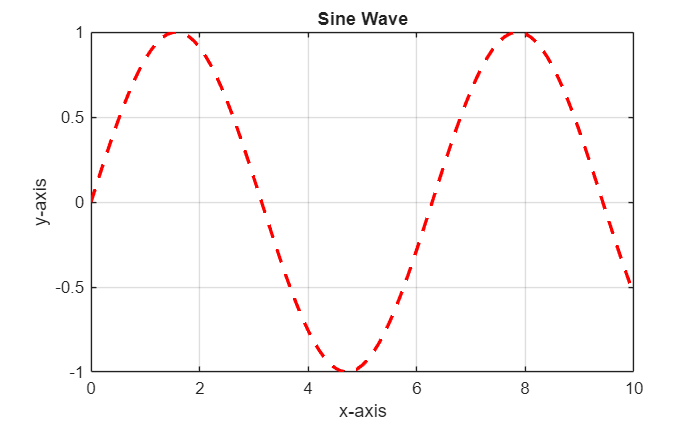

% plotting a graph
x = 0:0.1:10;
y = sin(x);
plot(x, y, 'r--', 'LineWidth', 2);
xlabel('x-axis');
ylabel('y-axis');
title('Sine Wave');
grid on;

%import the data
data = readtable('file.csv');

Error using readtable (line 19)
Unable to find or open 'file.csv'. Check the path and filename or file permissions.

head(data)

%question 1
x=[2;4;6];
f=[3;5;7];
u=[2.5;3.5;5.8];
target=2.5;

polyinterp(x,f,u)

function v=polyinterp(x,f,u)
    row=length(x);
    u_size=length(u);
    for k=1:u_size
        px=0;
        for i= 1:row
            Ljx=1;
            for j = 1:row
                if i~=j
                    Ljx = Ljx * ((u(k)-x(j))/(x(i)-x(j)));
                end
            end
            px=px+(Ljx*f(i));
        end
        disp(px);
    end
end
